# MIMO Lab/Project by Serhat Bakirtas sb7082

In this project, using Mingsheng Yin's indoor ray tracing data, I have investigated the effect of MCS selection and the number of streams utilized in a MIMO system on the throughput.

In this lab I will

- Construct antenna elements and arrays

- Compute the MIMO channel (frequency) response in an OFDM system at 28 GHz.

- Communicate using multiple streams using different MCSs and encoder-decoder pairs.

- Compute the Statistical Covariance and Statistical Precoder matrices.

- Compute and perform the Linear MMSE matrix.

- Perform encoding and decoding separately in each stream with different Modulations and TargetCodeRates.

- Try a number of mutual information thresholds for MCS selection and see the effect it has on Throughput.

- Try a number of stream numbers and see the effect it has on Throughput.

Since we simulate over the MCS selection threshold and the number of streams for each RE in the channel grid of size 732x14, Simulation 1 and Simulation 2  each take a little over 8 hours. Therefore, I haven't been able to either introduce channel impairment into the simulation, or re-run the simulation for a different receiver location. In addition, replicating the results by running this .mlx file might take prohibitively long.  The results of this simulations are given as  .mat files in the Github site.

## Loading Ray Tracing Data

First, we load the indoor ray tracing data.

load('roomPathData.mat');

## Receiver and Transmitter Position

We choose an arbitrary receiver index `rPosind` in LOS.

rPosind = 3; % Rx position index
rxPos  = pathData.rxPos(rPosind,:)'; % Rx position
txPos = pathData.txPos; % Tx position

## Simulation Parameters

Based on the receiver we chose, we obtain the gains, the delays and the angles of arrival and departure of each path.

%% Simulation Parameters
aoaAz = pathData.aoaAz(rPosind,:).';
aodAz = pathData.aodAz(rPosind,:).';
aoaEl = pathData.aoaEl(rPosind,:).';
aodEl = pathData.aodEl(rPosind,:).';
gain = pathData.gain(rPosind,:).';
dly = pathData.dly(rPosind,:).';
npaths = length(aoaAz);

## Creating Antenna Elements

We create a patch microstrip antenna element.

%% Creating Antenna Elements
fc = 28e9;  % Carrier frequency
elem = design(patchMicrostrip, fc);

Now, we rotate the element so that the boresight is along the x-axis.

elem.Tilt = 90;
elem.TiltAxis = [0,1,0];

## Creating Antenna Arrays

Now we construct two URAs for the transmitter and the receiver at 28 GHz, with $d=\frac{\lambda }{2}$ antenna separation. 

% Number of antennas
AAsizeTx = [4 4];        % Size of Tx Antenna Array
AAsizeRx = [2 2];        % Size of Rx Antenna Array
nantTx = prod(AAsizeTx); % Number of Tx Antennas
nantRx = prod(AAsizeRx); % Number of Rx Antennas
fc = 2.8e9;              % Carrier frequency
lambda = physconst('lightspeed')/fc; % Wavelength for 28 GHz
arrTx = phased.URA(AAsizeTx,lambda/2,'ArrayNormal','x'); % Rx Antennas
arrRx  = phased.URA(AAsizeRx,lambda/2,'ArrayNormal','x');% Tx Antennas

To simplify the tasks below, we use the `ArrayPlatform` class, given in Lab 8. To mitigate mutual coupling between the antennas we use `computeNormMatrix()` method.

% Tx Antenna Array at 28 GHz
arrPlatformTx = ArrayPlatform('elem', elem, 'arr', arrTx, 'fc', fc);
arrPlatformTx.computeNormMatrix();
% Rx Antenna Array at 28 GHz
arrPlatformRx = ArrayPlatform('elem', elem, 'arr', arrRx, 'fc', fc);
arrPlatformRx.computeNormMatrix();

## Simulating Frequency-Domain Channel

Using the `FDMIMOChan` class from Lab 8, we create a 28 GHz 4-D OFDM-MIMO channel matrix of size `nantRx*nantTx*732*14.`

fc = 28e9;                  % Carrier frequency
SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB
nsc = NRB*nscPerRB;
carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);
% Frequency Domain MIMO Channel
Enoise = -5; 
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformTx,...
    'rxArrPlatform', arrPlatformRx, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);
frameNum = 0;
slotNum = 0;
[chanGrid, ~] = fdchan.step(frameNum, slotNum); % Channel Grid for MIMO Channel

## Transmitter Power and Noise Variance

Here, we specify the transmitter power and the noise variance. 

%% Tx-Rx Powers and Noise Variance
txPow = 15;   % TX power in dBm
nf = 7;      % Noise figure
bw = 400e6;  % Bandwidth
Ekt = -174;  % Theremal noise
noiseVardB = nf + Ekt + 10*log10(bw); % Noise variance in dBm
noiseVar = db2pow(noiseVardB); % Noise variance in lineer scale
alpha = db2pow(txPow-noiseVardB)/nantTx; % \alpha in the LMMSE matrix computation

## Statistical Covariance Matrix and Statistical Precoder

Since it is difficult to estimate the phase, which is a small-scale varying parameter, we compute the statistical transmitter covariance matrix `Q_tx` and use it to obtain a single precoder which is used across all symbols and subcarriers.

Q_tx = zeros(nantTx);
for i=1:nsc
    for j=carrierConfig.SymbolsPerSlot
        Q_tx = Q_tx+chanGrid(:,:,i,j)'*chanGrid(:,:,i,j); 
    end
end
Q_tx = Q_tx/prod(size(chanGrid,3,4)); % Statistical Covariance Matrix
[W,~] = eig(Q_tx); % Eigenvalue Decomposition of Statistical Covariance Matrix
V = fliplr(W);     % eig function sorts the eigenvalues in ascending order

Given the number of streams `nstream`, the first `nstream` column of `V` constitutes the statistical precoder.

## PDSCH Simulation 1: Best MCS Selection Threshold

First we look at the effect of the MCS selection threshold for a fixed number of streams, `nstream=2`.  For each MCS selection threshold, we run a PDSCH simulation, where for each value we send `ntrial` blocks in each RE.

%% PDSCH Simulation Parameters
nstream = 2;         % Number of streams
Nsym = 100;          % Number of symbols per stream per trial
ntrial = 20;         % Number of trials
MCSselParam = [0.7 0.75 0.8 0.85 0.9]; %MCS selection threshold

Here MCS selection threshold means that for a MCS selection threshold $\beta$ and SNR $\gamma$, we choose the smallest MCS index $i$satisfying $\beta \mathrm{log}\left(1+\gamma \right)\le \mathrm{Spec}\ldotp \mathrm{Eff}\ldotp \left(i\right)$. To this end, I have written the function `chooseMCS.m` where one can chose to select MCSs from either NR PDSCH MCS Table Index 1 or NR PDSCH MCS Table Index 2. In this project, we stick with NR PDSCH MCS Table Index 1.

In the simulation below, for a given number of streams `nstream` and MCS selection threshold `beta`, in each RE 

- First, based on `nstream` we compute the  precoder matrix `F_pre, `the LMMSE equalization matrix `F_lmmse `and the LMMSE SNR of each stream`.`

- We choose MCS Index for each stream based on the LMMSE SNR of each stream. 

- Based on the MCS Index, we assign individual encoder-decoder pairs to each stream to meet the modulation order and the target code rate.

- For each stream, after encoding randomly generated bits `txBits` we generate a block of PDSCH symbols and store them in matrix `s`.

- We apply the precoder matrix to generate the precoded symbols `x=F_pre*s`

- We send the precoded symbols `x` through the frequency domain MIMO channel to obtain the received symbols `r=Hx+w`

- We perform LMMSE equalization to obtain the equalized symbols `y=F_lmmse*r`.

- In each stream, we decode the equalized symbols `y` to obtain `rxBits` and compare with `txBits`

- We repeat steps (4)-(8) `ntrial` times and store the average throughput. Here, our criterion is that if a block contains a bit error, it does not contribute anything to the throughput.

Below, we perform the simulation.

%% PDSCH Simulation Initialization & Pre-Allocation
ModOrder = zeros(length(MCSselParam),nstream);
CodeRate = zeros(length(MCSselParam),nstream);
pdschConfig = cell(1,nstream);
encDLSCH = cell(1,nstream);
decDLSCH = cell(1,nstream);
dlschLLRs= cell(1,nstream);
codedTrBlock = cell(1,nstream);
txBits  = cell(1,nstream);
pdschSymbols = cell(1,nstream);
rxSym = cell(1,nstream);
rxBits  = cell(1,nstream);
trBlkSizes = 1024;
s = zeros(nstream,trBlkSizes);
beta_best = zeros(nsc,carrierConfig.SymbolsPerSlot);
Throughput_best = zeros(nsc,carrierConfig.SymbolsPerSlot);
Throughput = zeros(nsc,carrierConfig.SymbolsPerSlot,length(MCSselParam));
F_pre = V(:,1:nstream); % Statistical Pre-coder Matrix
%% PDSCH Simulation for the Grid
for isc = 1:nsc
    for isym = 1:carrierConfig.SymbolsPerSlot
        %% Channel Matrix
        H = chanGrid(:,:,isc,isym); % MIMO Channel Matrix
        G = H*F_pre;    % Equivalent Channel Matrix After Precoding
        Q_lmmse = inv(alpha*G'*G+ eye(nstream));
        F_lmmse = (G'*G+eye(nstream)/alpha)\G'; % LMMSE Equalization Matrix
        gamma_lmmse = real(diag(1./Q_lmmse))-1; % SNR's in each channel
        C = log2(1+gamma_lmmse)'; % Spectral Efficiency of LMMSE in each stream
        %% PDSCH Simulation Initialization & Pre-Allocation
        corr_block = zeros(length(MCSselParam),nstream);
        %% PDSCH Simulation for the RE
        for imcs=1:length(MCSselParam)
            beta = MCSselParam(imcs);
            % MCS Selection
            MCSTable = 1; % MCS Index Table 1
            [Modulation,TargetCodeRate,MO] = chooseMCS(gamma_lmmse/nstream,beta,MCSTable);
            CodeRate(imcs,:) = TargetCodeRate;
            ModOrder(imcs,:) = MO;
            for istream=1:nstream
                pdschConfig{istream} = nrPDSCHConfig(...
                    'Modulation', Modulation(istream), ...
                    'PRBSet', (0:NRB-1), ...
                    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
                    'EnablePTRS', 1,...
                    'PTRS', nrPDSCHPTRSConfig());
                encDLSCH{istream} = nrDLSCH('MultipleHARQProcesses', false, ...
                    'TargetCodeRate', TargetCodeRate(istream));
                
                decDLSCH{istream}= nrDLSCHDecoder('MultipleHARQProcesses', false, ...
                    'TargetCodeRate', encDLSCH{istream}.TargetCodeRate, ...
                    'LDPCDecodingAlgorithm', 'Layered belief propagation');
            end
            for itrial = 1:ntrial
                for istream = 1:nstream
                    txBits{istream}= randi([0 1],trBlkSizes, 1);
                    encDLSCH{istream}.setTransportBlock(txBits{istream},0);
                    rv = 0;
                    codedTrBlock{istream} = encDLSCH{istream}(pdschConfig{istream}.Modulation, ...
                        pdschConfig{istream}.NumLayers, MO(istream)*trBlkSizes, rv);
                    pdschSymbols{istream} = nrPDSCH(carrierConfig, pdschConfig{istream}, ...
                        codedTrBlock{istream});
                    s(istream,:)= pdschSymbols{istream}.';
                end
                %% Channel
                x = F_pre*s; % Precoded Tx Symbol
                w = sqrt(nstream/alpha/2)*(randn(nantRx,trBlkSizes)+1i*randn(nantRx,trBlkSizes)); %AWGN
                r = H*x+w; % Received Symbols
                y = F_lmmse*r; % Equalized Rx symbols (LMMSE)
                %% Receiver
                for istream = 1:nstream
                    [dlschLLRs{istream}, rxSym{istream}] = nrPDSCHDecode(carrierConfig, ...
                        pdschConfig{istream}, y(istream,:).', nstream/alpha);
                    decDLSCH{istream}.TransportBlockLength = trBlkSizes;
                    harqId = 0;
                    decDLSCH{istream}.resetSoftBuffer(harqId);
                    rv = 0;
                    rxBits{istream} = decDLSCH{istream}(dlschLLRs{istream},...
                        pdschConfig{istream}.Modulation,pdschConfig{istream}.NumLayers,rv);
                    if txBits{istream}==rxBits{istream}
                        corr_block(imcs,istream) = corr_block(imcs,istream)+1;
                    end
                end
            end
        end
        Throughput(isc,isym,:) = sum(corr_block.*ModOrder.*CodeRate,2)/ntrial; % Average SumRate
        [R_max,ind_max] = max(Throughput(isc,isym,:));
        beta_best(isc,isym) = MCSselParam(ind_max); % Best Choice Beta Maximizing Throughput
        Throughput_best(isc,isym) = R_max;
    end
end

## Simulation Results 1

We now look at the best MCS selection threshold for each RE when `nstream=2`.

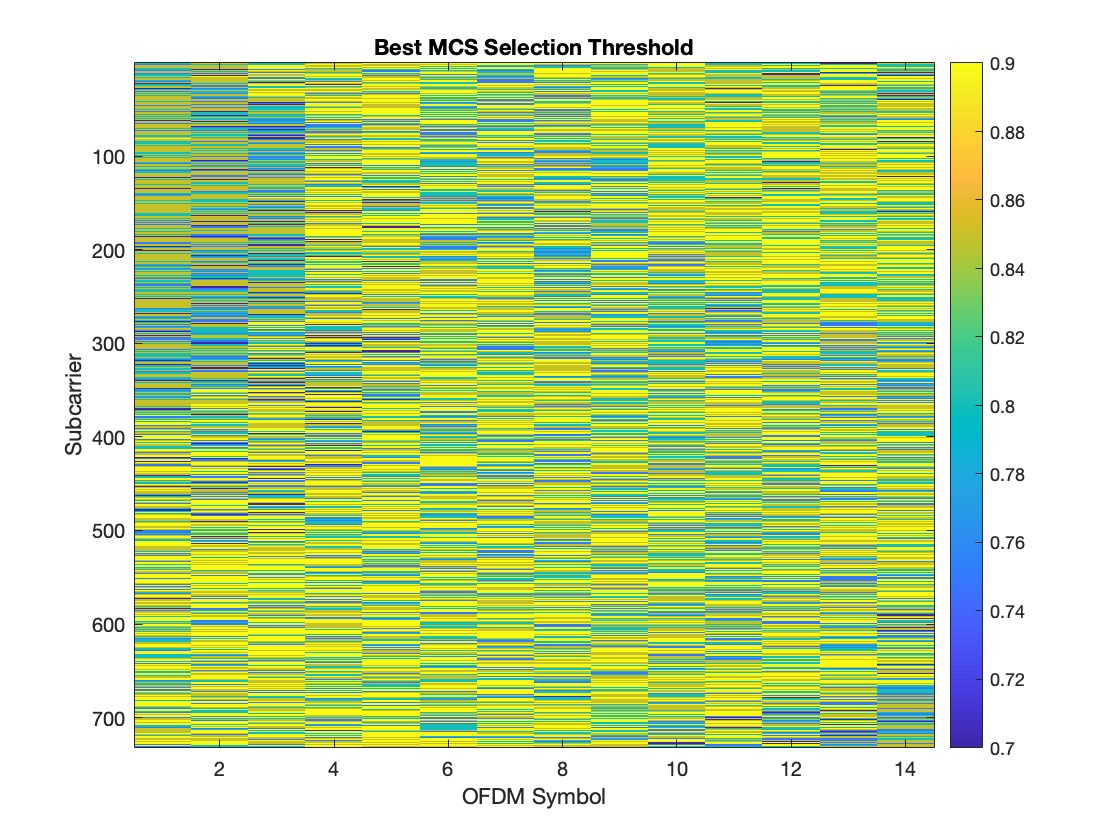

figure
imagesc(beta_best);
colorbar()
title('Best MCS Selection Threshold')
xlabel('OFDM Symbol')
ylabel('Subcarrier')

Now, we look at the throughputs corresponding to the MCS selection thresholds given above.

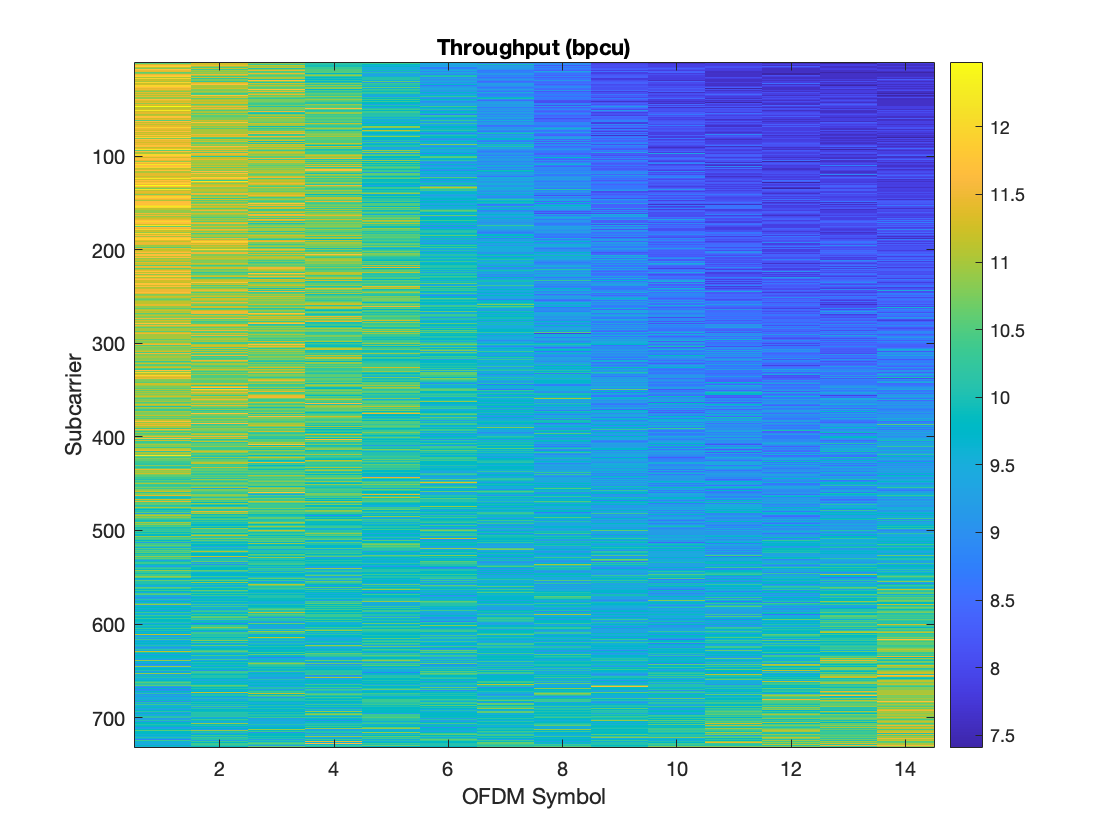

figure
imagesc(Throughput_best)
colorbar;
title('Throughput (bpcu)')
xlabel('OFDM Symbol')
ylabel('Subcarrier')

Finally we look at the throughput of each MCS selection threshold, averaged over the whole grid. 

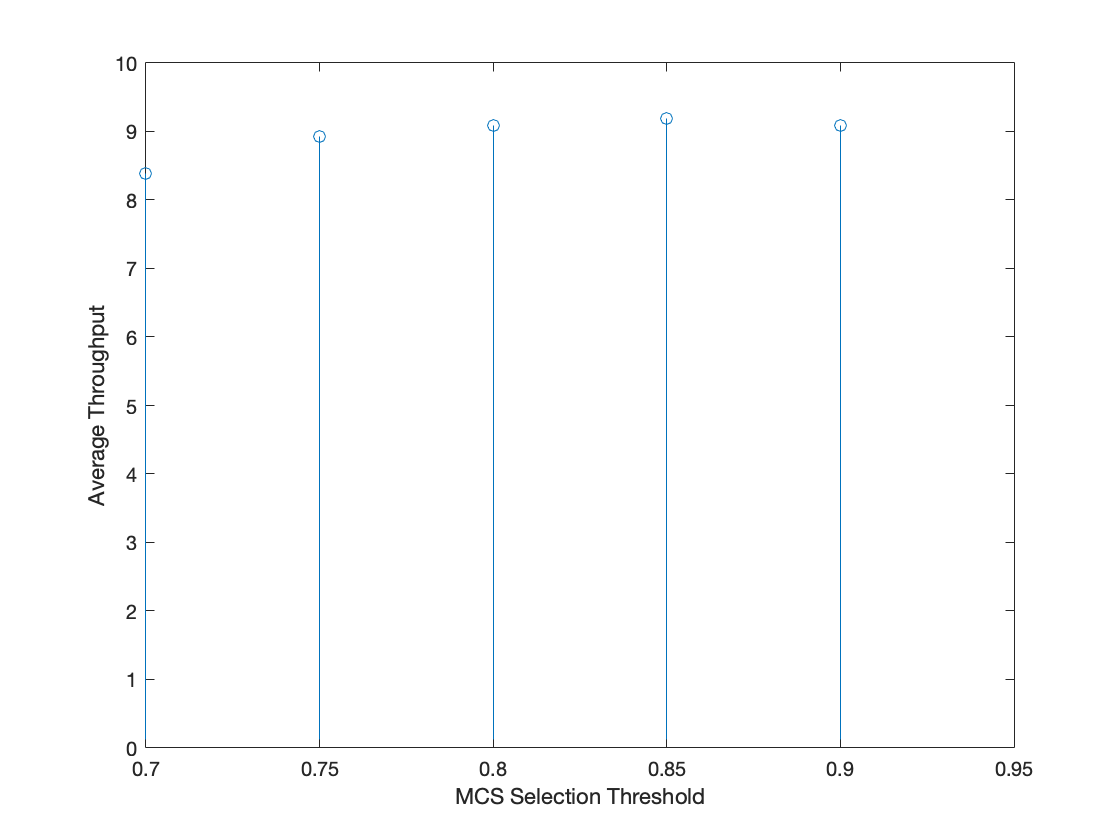

figure
stem(MCSselParam,squeeze(mean(Throughput,[1 2])));
xlabel('MCS Selection Threshold');
ylabel('Average Throughput (bpcu)')

From above, we see that on average $\beta =0\ldotp 80$ is the best choice for MCS selection threshold, while the average throughput doesn't vary too much, when the MCS selection threshold is in `[0.75,0.90],` 

## PDSCH Simulation 2: Best Number of Streams

Now, we fix $\beta =0\ldotp 80$ and run our simulation for different number of streams and see its effect on the throughput. Except for fixing $\beta \;$and varying `nstream`, we follow the same steps explained in Simulation 1.

%% PDSCH Simulation Parameters
nstreamselParam = 1:4;         % Number of streams
Nsym = 100;          % Number of symbols per stream per trial
ntrial = 20;         % Number of trials
beta = 0.80;         %MCS selection threshold
%% PDSCH Simulation Initialization & Pre-Allocation
Throughput_2 = zeros(nsc,carrierConfig.SymbolsPerSlot,length(nstreamselParam));
Throughput_best = zeros(nsc,carrierConfig.SymbolsPerSlot);
for nstream=nstreamselParam
    ModOrder = zeros(1,nstream);
    CodeRate = zeros(1,nstream);
    pdschConfig = cell(1,nstream);
    encDLSCH = cell(1,nstream);
    decDLSCH = cell(1,nstream);
    dlschLLRs= cell(1,nstream);
    codedTrBlock = cell(1,nstream);
    txBits  = cell(1,nstream);
    pdschSymbols = cell(1,nstream);
    rxSym = cell(1,nstream);
    rxBits  = cell(1,nstream);
    trBlkSizes = 1024;
    s = zeros(nstream,trBlkSizes);
    
    F_pre = V(:,1:nstream); % Statistical Pre-coder Matrix
    %% PDSCH Simulation for the Grid
    for isc = 1:nsc
        for isym = 1:carrierConfig.SymbolsPerSlot
            %% Channel Matrix
            H = chanGrid(:,:,isc,isym); % MIMO Channel Matrix
            G = H*F_pre;    % Equivalent Channel Matrix After Precoding
            Q_lmmse = inv(alpha*G'*G+ eye(nstream));
            F_lmmse = (G'*G+eye(nstream)/alpha)\G'; % LMMSE Equalization Matrix
            gamma_lmmse = real(diag(1./Q_lmmse))-1; % SNR's in each channel
            C = log2(1+gamma_lmmse)'; % Spectral Efficiency of LMMSE in each stream
            %% PDSCH Simulation Initialization & Pre-Allocation
            corr_block = zeros(1,nstream);
            %% PDSCH Simulation for the RE
            % MCS Selection
            MCSTable = 1; % MCS Index Table 1
            [Modulation,TargetCodeRate,MO] = chooseMCS(gamma_lmmse/nstream,beta,MCSTable);
            CodeRate= TargetCodeRate;
            ModOrder = MO;
            for istream=1:nstream
                pdschConfig{istream} = nrPDSCHConfig(...
                    'Modulation', Modulation(istream), ...
                    'PRBSet', (0:NRB-1), ...
                    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
                    'EnablePTRS', 1,...
                    'PTRS', nrPDSCHPTRSConfig());
                encDLSCH{istream} = nrDLSCH('MultipleHARQProcesses', false, ...
                    'TargetCodeRate', TargetCodeRate(istream));
                
                decDLSCH{istream}= nrDLSCHDecoder('MultipleHARQProcesses', false, ...
                    'TargetCodeRate', encDLSCH{istream}.TargetCodeRate, ...
                    'LDPCDecodingAlgorithm', 'Layered belief propagation');
            end
            for itrial = 1:ntrial
                for istream = 1:nstream
                    txBits{istream}= randi([0 1],trBlkSizes, 1);
                    encDLSCH{istream}.setTransportBlock(txBits{istream},0);
                    rv = 0;
                    codedTrBlock{istream} = encDLSCH{istream}(pdschConfig{istream}.Modulation, ...
                        pdschConfig{istream}.NumLayers, MO(istream)*trBlkSizes, rv);
                    pdschSymbols{istream} = nrPDSCH(carrierConfig, pdschConfig{istream}, ...
                        codedTrBlock{istream});
                    s(istream,:)= pdschSymbols{istream}.';
                end
                %% Channel
                x = F_pre*s; % Precoded Tx Symbol
                w = sqrt(nstream/alpha/2)*(randn(nantRx,trBlkSizes)+1i*randn(nantRx,trBlkSizes)); %AWGN
                r = H*x+w; % Received Symbols
                y = F_lmmse*r; % Equalized Rx symbols (LMMSE)
                %% Receiver
                for istream = 1:nstream
                    [dlschLLRs{istream}, rxSym{istream}] = nrPDSCHDecode(carrierConfig, ...
                        pdschConfig{istream}, y(istream,:).', nstream/alpha);
                    decDLSCH{istream}.TransportBlockLength = trBlkSizes;
                    harqId = 0;
                    decDLSCH{istream}.resetSoftBuffer(harqId);
                    rv = 0;
                    rxBits{istream} = decDLSCH{istream}(dlschLLRs{istream},...
                        pdschConfig{istream}.Modulation,pdschConfig{istream}.NumLayers,rv);
                    if txBits{istream}==rxBits{istream}
                        corr_block(1,istream) = corr_block(1,istream)+1;
                    end
                end
            end
            Throughput_2(isc,isym,nstream) = sum(corr_block.*ModOrder.*CodeRate',2)/ntrial;
        end
    end
end

## Simulation 2 Results

Here, we display the throughput for each RE, averaged over `ntrial=20` trials, when $\beta =0\ldotp 80$.

Below, we display the throughput for `nstream=1`. We see that it is constant across the blocks.

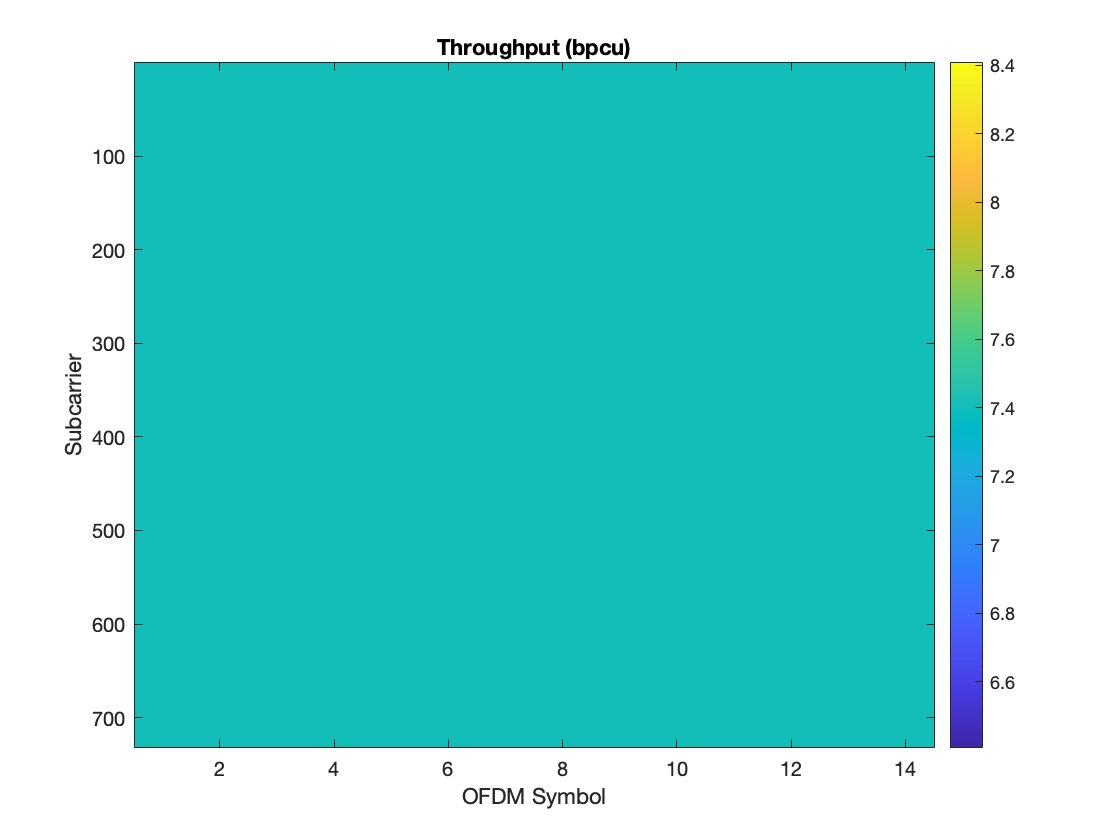

figure
imagesc(Throughput_2(:,:,1))
colorbar;
title('Throughput (bpcu)')
xlabel('OFDM Symbol')
ylabel('Subcarrier')

Now, we display the throughput for `nstream=2.`

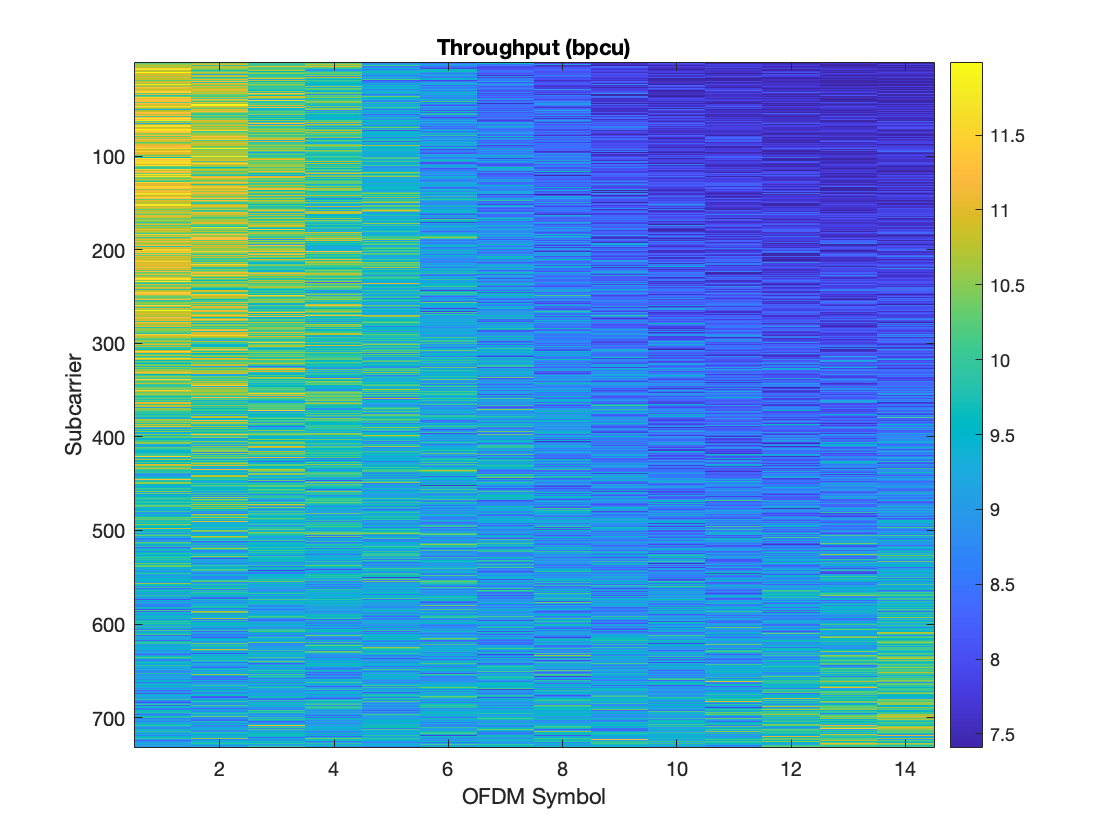

figure
imagesc(Throughput_2(:,:,2))
colorbar
title('Throughput (bpcu)')
xlabel('OFDM Symbol')
ylabel('Subcarrier')

Now, we display the throughput for `nstream=3.`

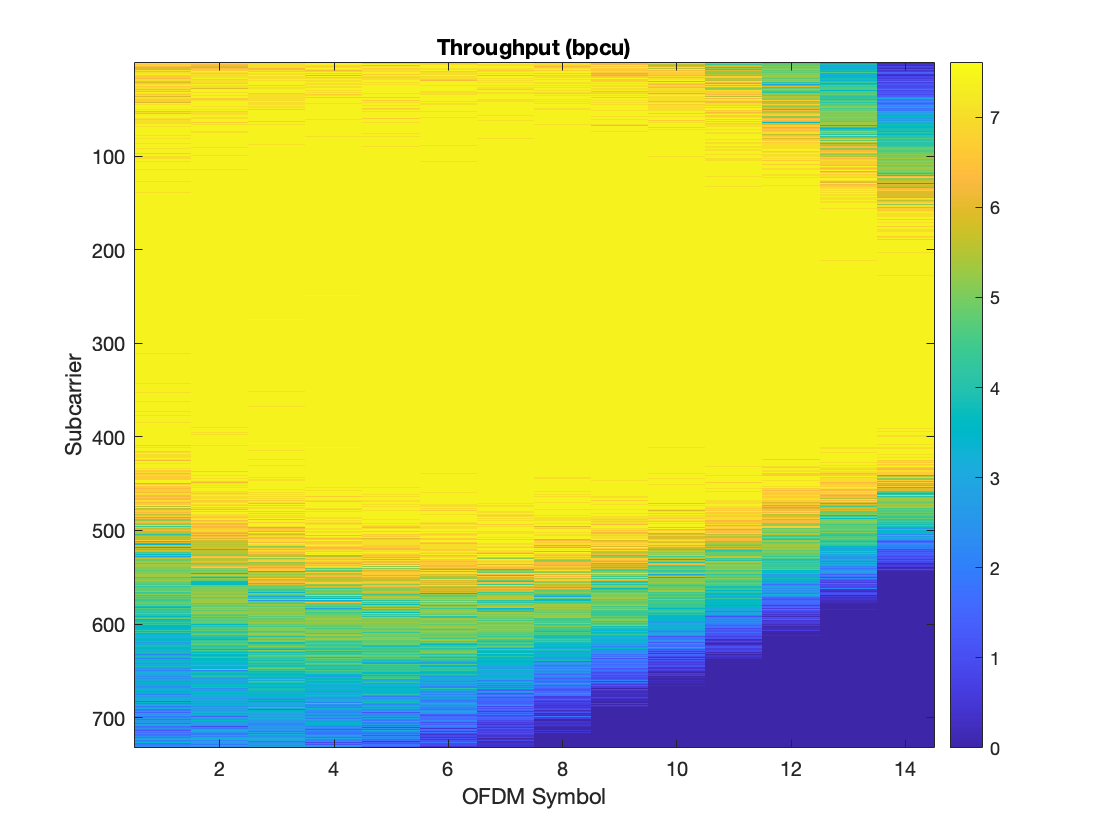

figure
imagesc(Throughput_2(:,:,3))
colorbar
title('Throughput (bpcu)')
xlabel('OFDM Symbol')
ylabel('Subcarrier')

Now, we display the throughput for `nstream=4.`

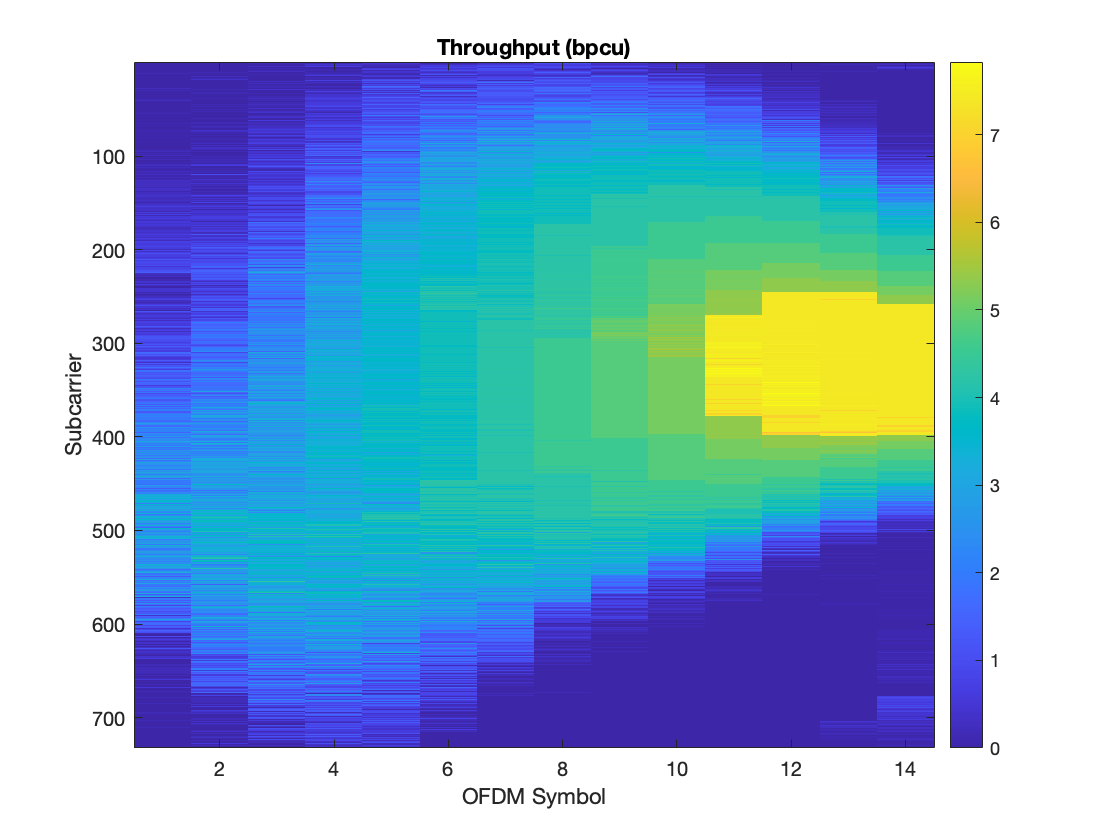

figure
imagesc(Throughput_2(:,:,4))
colorbar
title('Throughput (bpcu)')
xlabel('OFDM Symbol')
ylabel('Subcarrier')

Furthermore, for each value of `nstream` we average the throughput over each RE over `ntrial=20` trials.

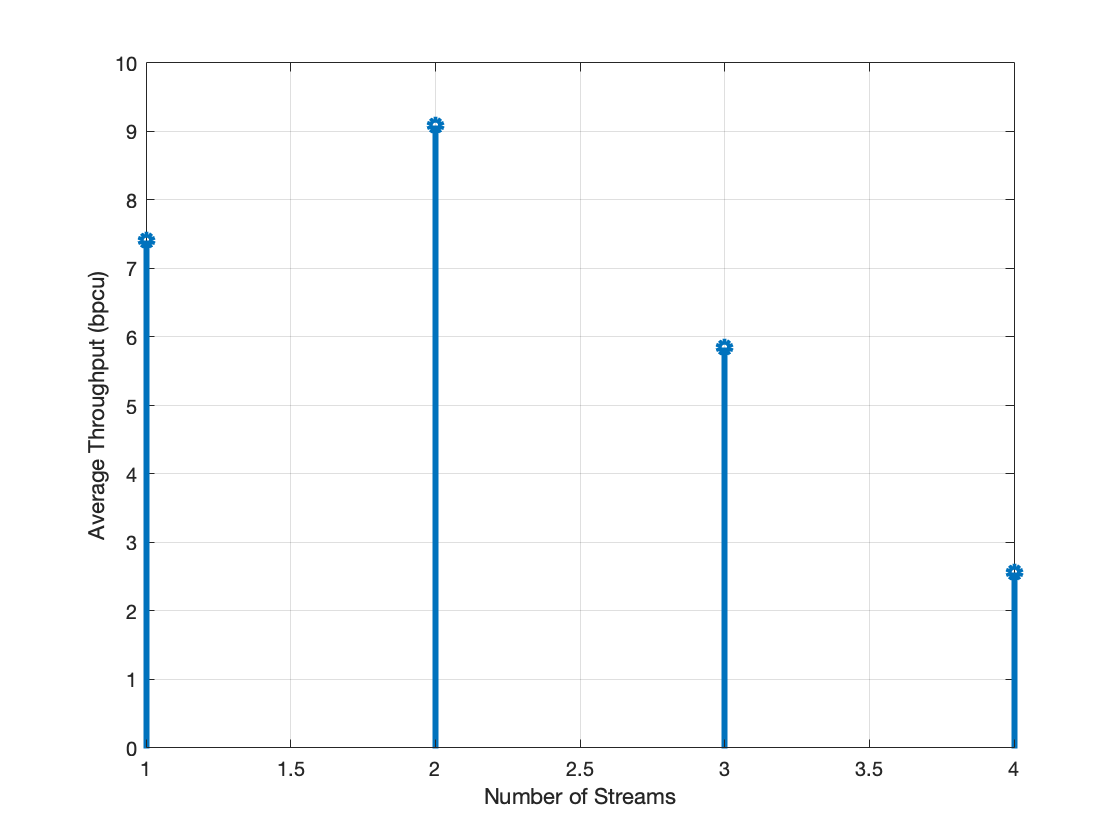

figure
stem(nstreamselParam,squeeze(mean(Throughput_2,[1,2])),'linewidth',3)
xlabel('Number of Streams')
ylabel('Average Throughput (bpcu)')
grid on;

We see that in this case utilizing `nstream=2` channels is the best option for Receiver 3. Also, simply utilizing only one channel yields a comparable throughput. 